**Obstacles Modeling**

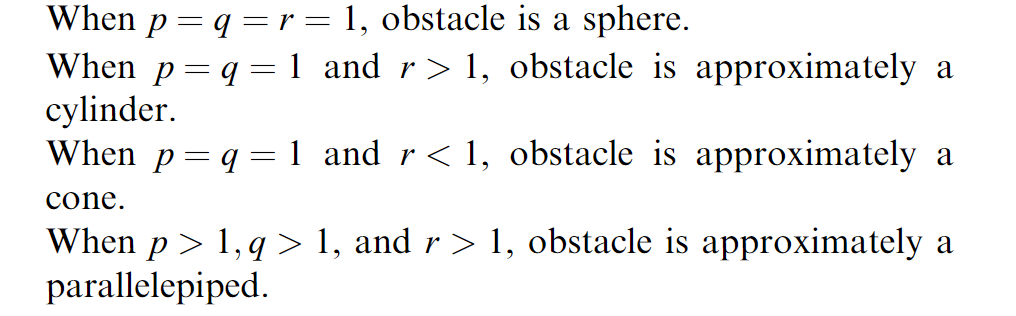

clc, clear, close all

% Object's origin point
x0 = sym(50);
y0 = sym(0);
z0 = sym(0);

% Object's axis length
a = sym(10);
b = sym(10);
c = sym(50);

% Index parameters
p = sym(1);
q = sym(1);
r = sym(5);

% UAV position XYZ
syms X Y Z
assume([X Y Z], 'real')
% assumptions([X Y Z])

% Object Shape Equation
Gamma(X, Y, Z) = ((X - x0) / a).^(2*p) + ((Y - y0) / b).^(2*q) + ((Z - z0) / c).^(2*r);
Object = Gamma == 1;

% Plot the surface
figure;
fimplicit3(Gamma == 1, [-10 100 -20 20 0 100],'linewidth',0.01)
colorbar
colormap pink
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D plot of equation');

**Original Fluid**

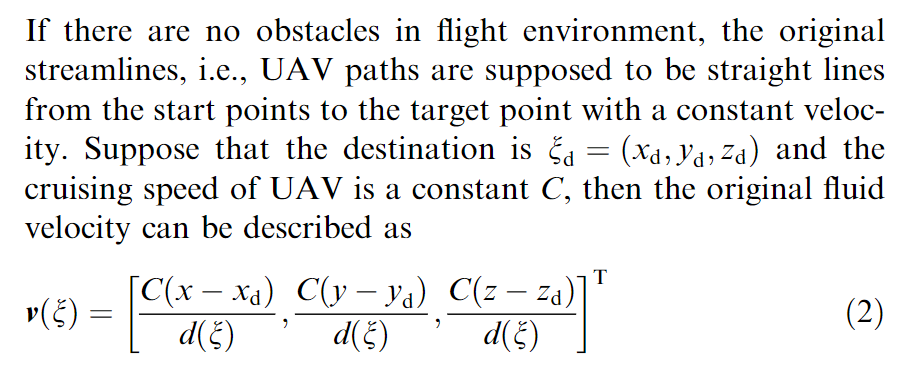

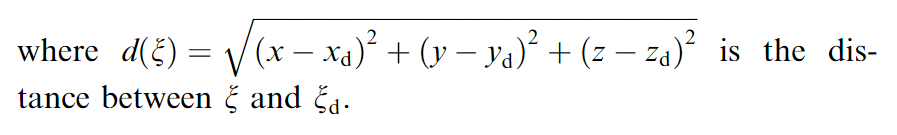

C = sym(2);   % [m/s]?UAV cruising speed
% Target Destination
xd = sym(-50);
yd = sym(0);
zd = sym(-3);

dist(X,Y,Z) = sqrt((X - xd)^2 + (Y - yd)^2 + (Z - zd)^2);

u(X,Y,Z) = [C*(X - xd)/dist; C*(Y - yd)/dist; C*(Z - zd)/dist] ;

**Unit normal vector along outward on the surface of obstacles**

dGdx = diff(Gamma, X);
dGdy = diff(Gamma, Y);
dGdz = diff(Gamma, Z);

n = [dGdx; dGdy; dGdz];  % Check Transpose (could be wrong)

**Unit tangential vector**

 Note that $F=\Gamma$ (different literature)

t = [dGdy; -dGdx; 0];

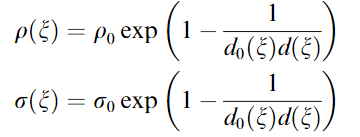

syms rho0 sigma0 epsilonbar
dist_obj(X,Y,Z) = sqrt((X - x0)^2 + (Y - y0)^2 + (Z - z0)^2);

rho0 = sym(3);     % Repulsive parameter (rho >= 0)
sigma0 = sym(0.2);    % Tangential parameter 

rho = rho0 * exp(1 - 1/(dist_obj*dist));
sigma = sigma0 * exp(1 - 1/(dist_obj*dist));

**Saturation function **$\tau$

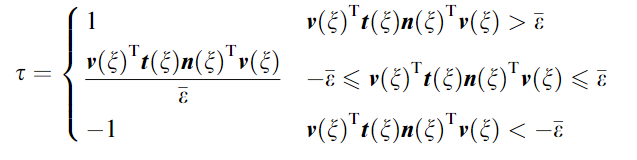

% checkVal = u'*t*n'*u
% epsilonbar =  2  % small positive threshold
% epsilonbar = subs(epsilonbar, 2)
% 
% % Need to substitue value first before using the logic
% if checkVal > epsilonbar
%     tao = sym(1)
% elseif (checkVal >= -epsilonbar) && (checkVal <= epsilonbar)
%     tao = (u'*t*n'*u)/epsilonbar
% elseif checkVal < -epsilonbar
%     tao = sym(-1)
% end

**Modular Matrix (Perturbation Matrix)**

**from **Yao, P., Wang, H., & Su, Z. (2015). UAV feasible path planning based on disturbed fluid and trajectory propagation. *Chinese Journal of Aeronautics*, *28*(4), 1163–1177. [https://doi.org/10.1016/J.CJA.2015.06.014](https://doi.org/10.1016/J.CJA.2015.06.014)

Another paper

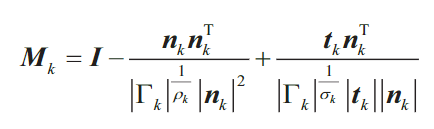

M = eye(3) - n*n'/(abs(Gamma)^(1/rho)*(n')*n)...
    + t*n'/(abs(Gamma)^(1/sigma)*norm(t)*norm(n));  % tao is removed for now

**Interfered Fluid Velocity **$u\bar$  

% ubar(X, Y, Z) = M*u;

**Path from Streamline**

Obtain from integrating $u\bar$ recursively

tsim = 150; % seconds
sf = 0; % Shape-following demand (1=on, 0=off)
tnow = 0;
dt = 1;
Xini = 0;
Yini = 0;
Zini = 0;

ubar = zeros(3);
Wp = zeros(3,tsim+1);
Wp(:,1) = [Xini; Yini; Zini];

% check = subs(ubar, [X,Y,Z], [Xnow,Ynow,Znow])
% double(ubar(Xnow, Ynow, Znow))

for j = 1:tsim

    xx = Wp(1,j);
    yy = Wp(2,j);
    zz = Wp(3,j);

    if n(xx,yy,zz)'*u(xx,yy,zz) < 0 || sf == 1
        disp('case 1 activated')
        Mm = M(xx,yy,zz);
    elseif n(xx,yy,zz)'*u(xx,yy,zz) >= 0 && sf == 0
        disp('case 2 activated')
        Mm = eye(3);
    end
    
    ubar = M*u;
    Wp(:,j+1) = Wp(:,j) + double(ubar(Wp(1,j), Wp(2,j), Wp(3,j))) * dt;
    
end

case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 1 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


case 2 activated


**Plotting the path**

figure
fimplicit3(Gamma == 1, [-10 100 -20 20 0 100],'linewidth',0.01)
colormap pink
hold on, grid on, axis equal
plot3(Wp(1,:), Wp(2,:), Wp(3,:), 'LineWidth', 1.5)


scatter3(Wp(1,1), Wp(2,1), Wp(3,1), 'filled', 'r')
xlabel('X'); ylabel('Y'); zlabel('Z');


figure
subplot(3,1,1)
plot(Wp(1,:),'o-')
subplot(3,1,2)
plot(Wp(2,:),'o-')
subplot(3,1,3)
plot(Wp(3,:),'o-')